# 22-2 Robot Vision - Image Formation

Camera Parameters Setting

% parameters
camera_focal = 1000; % fx=fy
camera_center = [320 240]; % cx, cy
camera_res = [640 480]; % 640 x 480

Read the 3-D coordinate points into the workspace.

% Load Point Cloud
% load('xyzPoints');
xyzPoints = load("~/study/강의/rv/box.xyz"); % x, y, z (N x 3)

Plot 3D

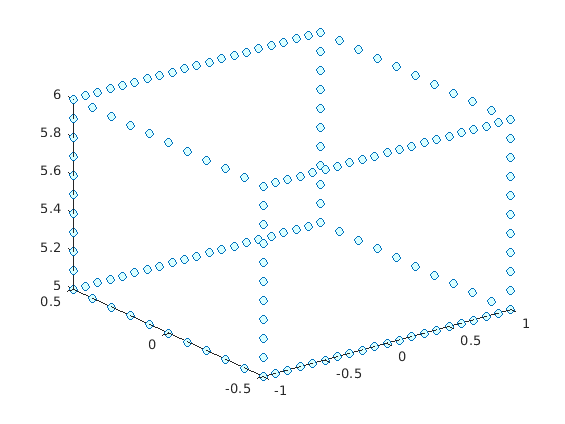

plot3(xyzPoints(:,1), xyzPoints(:,2), xyzPoints(:,3), 'o', 'MarkerFaceColor', '#D9FFFF');

Load a point cloud in the homogeneous coordinate

xyz_homo = [xyzPoints ones(length(xyzPoints),1)]'; % (4(x,y,z,1) x N)

Camera matrix

K = [camera_focal 0 camera_center(1); 0 camera_focal camera_center(2); 0 0 1];

Generate images for each camera pose

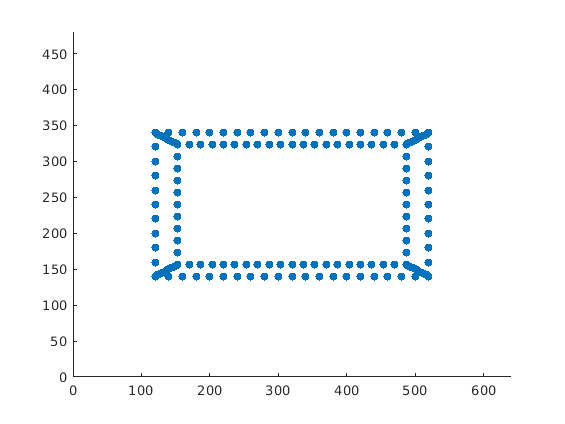

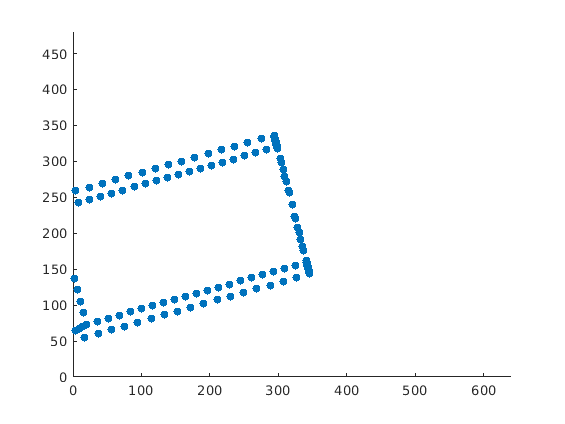

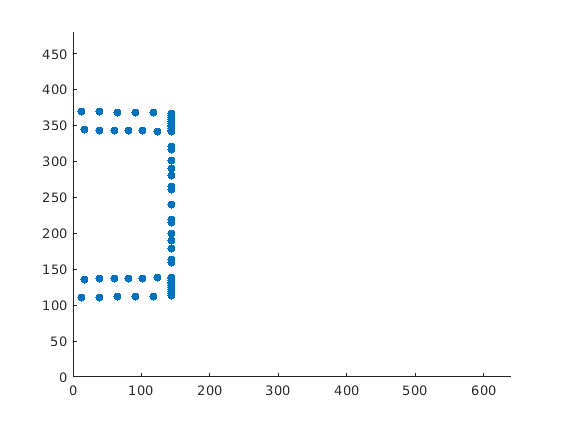

camera_pos = [0 0 0; 1 0 0; 1 0 1];
camera_ori = [0 0 0; -pi/12 0 0; 0 pi/18 0]; % rad

for i = 1:size(camera_pos, 1)
    % Projection matrix
    Rc = Rz(camera_ori(i,3)) * Ry(camera_ori(i,2)) * Rz(camera_ori(i,1));
    Rt = [Rc' -Rc'*camera_pos(i,:)'];
    P = K * Rt;
    
    % Project Points
    x = P * xyz_homo;
    x(1,:) = x(1,:)./x(3,:);
    x(2,:) = x(2,:)./x(3,:);
    x(3,:) = 1;
    
    % make image
    img = zeros(camera_res);
    img = x(1:2,:);
    figure;
    scatter(img(1,:), img(2,:), 'filled');
    axis([0 640 0 480]);
end

function rot_x = Rx(rx)
    rot_x = [1 0 0; 0 cos(rx) -sin(rx); 0 sin(rx) cos(rx)];    
end
function rot_y = Ry(ry)
    rot_y = [cos(ry) 0 sin(ry); 0 1 0; -sin(ry) 0 cos(ry)];
end
function rot_z = Rz(rz)
    rot_z = [cos(rz) -sin(rz) 0; sin(rz) cos(rz) 0; 0 0 1];
end